clear
format longG
load Day_15_input.mat
%puzzle_input(end+1:4096) = 0;

droid = IntCode('puzzle_input', puzzle_input, 'instance_nr', 1, 'setting',1);
droid.setup(0);
direction = N;
starting_position = [0,0];
droid_position = starting_position;
areamap = [string(starting_position),"."];
indexmap = 1;
status = 0;
first_run = true;
% Wall follower algorithm, explore both ways to make a more complete map
explored_both_ways = false;
while not(explored_both_ways)
    % direction = random('unid',4);
    status = droid.step(direction);
    coord = updatecoordfromdirection(droid_position, direction);
    switch status
        case 0
            % Droid hit wall, position did not change
            % Update map with wall and next direction
            s = "#";
            if first_run, newdir = CCW;else newdir = CW; end
            direction = turn(direction, newdir);
        case 1
            % Droid moved one step in that direction
            s = ".";
            droid_position = coord;
            if first_run, newdir = CW;else newdir = CCW; end
            direction = turn(direction, newdir);
        case 2
            % Success, droid is at oxygen tank. Restart changing direction
            s = "O";
            if not(first_run)
                explored_both_ways = true;
                areamap2 = areamap;
            else
                first_run = false;
                load Day_15_input.mat
                droid = IntCode('puzzle_input', puzzle_input, 'instance_nr', 1, 'setting',1);
                droid.setup(0);
                droid_position = starting_position;
                direction = N;
                areamap1 = areamap;
                areamap = [string(starting_position),"."];
            end
        otherwise
            disp(['unknown status ',status]);
            return
    end
    areamap = [areamap; string(coord) s]; indexmap = indexmap+1;
end
areamap = [areamap1;areamap2];
areamapwalls = unique(double(areamap(areamap(:,3)=="#",1:2)),'rows');
areamapoxygen = unique(double(areamap(areamap(:,3)=="O",1:2)),'rows');
figure
plot(areamapwalls(:,1), areamapwalls(:,2),'k*'); hold

Current plot held


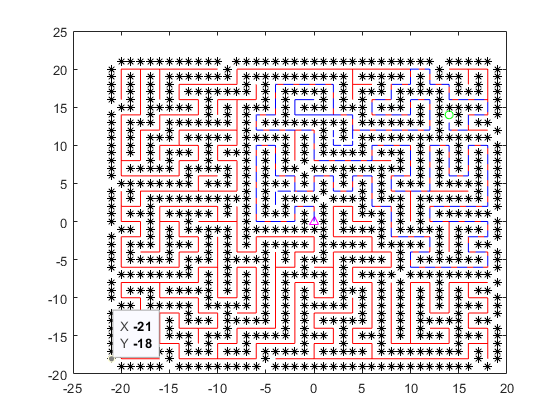

Current plot released


plot(areamapoxygen(:,1), areamapoxygen(:,2),'gO');
plot(0,0,'Marker','^','Color','m')
path1 = double(areamap1(areamap1(:,3)==".",1:2));
path2 = double(areamap2(areamap2(:,3)==".",1:2));
plot(path2(:,1), path2(:,2),'r');
plot(path1(:,1), path1(:,2),'b--'); hold


% A bit of cheating, see if the shortest path is the number of overlapping cells between both paths
% (Max's algorithm)
common = 0;
path1 = unique(path1,'rows');
path2 = unique(path2,'rows');
for i=1:size(path1,1)
    common = common + double(ismember(path1(i,:),path2,'rows'));
end
solution = common % Yep that worked

solution =    232


## Part 2, propagate oxygen

% While the optimal solution should be to find the furthest path from O, let's
% do a simple visualisation intuitive version. Start from Oxygen, and "convert"
% nearby empty cells to Oxygen repeat until all cells are filled
n_cells = size(unique([path1;path2],"rows"),1) % number of empty cells;

n_cells =    798


oxy_cells = 0;
areamapc = double(areamap(:,1:2));
areamapc(:,3) = double(char(areamap(:,3)));
areamapc(areamapc(:,3)==46,3)=1; % 1 = air
areamapc(areamapc(:,3)==35,3)=0; % 0 = wall
areamapc(areamapc(:,3)==79,3)=2; % 2 = oxygen
areamapc = unique(areamapc,"rows");
[X,Y] = meshgrid(min(areamapc(:,1)):max(areamapc(:,1)), min(areamapc(:,2)):max(areamapc(:,2)));
Z = zeros(size(X));
for ix=1:size(X,1)
    for iy=1:size(Y,1)
        val = areamapc( (areamapc(:,1)==X(ix,iy)) & (areamapc(:,2)==Y(ix,iy)),3);
        if not(isempty(val))
            Z(ix,iy) = val;
        end
    end
end



function m = expandoxygen(xymap)

end
function c = updatecoordfromdirection(coord, direction)
c = double(coord);
switch direction
    case N
        c(2) = c(2) + 1;
    case S
        c(2) = c(2) - 1;
    case E
        c(1) = c(1) + 1;
    case W
        c(1) = c(1) - 1;
end
end
function NORTH = N, NORTH = 1;end
function SOUTH = S, SOUTH = 2;end
function WEST  = W, WEST = 3;end
function EAST  = E, EAST = 4;end
function CLOCKWISE        = CW,  CLOCKWISE  = 1; end
function COUNTERCLOCKWISE = CCW, COUNTERCLOCKWISE = 2; end
function d = turn(direction,verso)
switch direction
    case N
        if verso==CW,d=E;else d=W;end
    case S
        if verso==CW,d=W;else d=E;end
    case E
        if verso==CW,d=S;else d=N;end
    case W
        if verso==CW,d=N;else d=S;end
end
end

function V = changeverso(currentverso)
if currentverso==CW
    V = CCW;
else
    V = CW;
end
end